%addpath 'iwave\development\matlab'

load_parameters

t_end = 0.01; % secs
t = 0 : t_step : t_end;

%% generate signal and noise
f_axion = generate_axion_frequency(t, f_sampling, t_coherence, f_a, axion_linewidth);
signal = generate_axion_signal(t, f_sampling, f_axion, axion_power);
noise_power = calculate_noise_power(f_sampling, T);
noise = generate_thermal_noise(t, f_sampling, noise_power);

band_width = 1000;
f_0 = f_a;
band = [f_0-band_width/2, f_0+band_width/2];
Q_resonator = f_0 / band_width;

iwave_input_f = prepare_iwave_input(signal + noise, f_0, band_width, f_sampling);

%% run iwave
tau_iwave = 3e-4;

% front to chop off
start_secs = 0.0025;
assert(start_secs < t(end)/3)
start = round(start_secs * f_sampling);

[f_iwave, amp] = run_iwave(iwave_input_f, f_sampling, f_0, tau_iwave);

INPUT_DATA = iwave_input_f;
f_guess = f_0
[dout, qout, amp, error, freq, fstate] = iwave_my_run(f_sampling, tau_iwave, f_guess, 0, INPUT_DATA);

STATE_PS = iwave_setup(f_sampling, tau_iwave, f_guess, 0);
f = zeros(1, length(INPUT_DATA));
for i = 1 : length(INPUT_DATA)
    [STATE_PS, pdout, pqout, paout, peout, pfout, pfstateout] = iwave_step(STATE_PS, INPUT_DATA(i));
    f(i) = pfout;
end

% don't need to plot every single point
div = 1000;

slice = (1:div:length(t));
t_small       = t(slice);
f_axion_small = f_axion(slice);
f_iwave_small = f_iwave(slice);
amp_small = amp(slice);

my_f_iwave = freq(slice);
my_dout = dout(slice);
f_small = f(slice);

start = round(start / div);

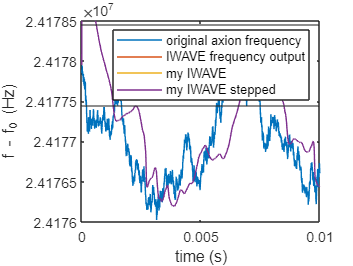

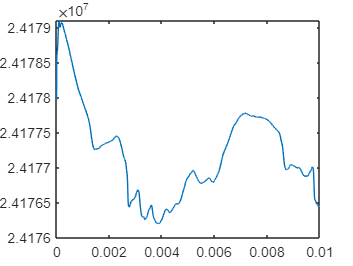

% plot iwave before and after
figure

plot(t_small, f_axion_small-0, 'DisplayName','original axion frequency')
y_lim = ylim();
hold on
plot(t_small, f_iwave_small-0, 'DisplayName','IWAVE frequency output')

plot(t_small, my_f_iwave, 'DisplayName','my IWAVE')

plot(t_small, f_small, 'DisplayName','my IWAVE stepped')

ylim(y_lim)
legend()
xlabel('time (s)')
ylabel('f - f_0 (Hz)')

yline(band, 'HandleVisibility','off')